# Eigen-Decomposition & Singular Value Decomposition

Note that the costs of eigen-decomposition and SVD are as

- eigen-decomposition: $9n^3$ if matrix is with size $n\times n$.

- SVD: $14nk^2+8k^3$ if matrix is with size $n\times k ~ (n\geq k)$ .

Please refer to Nicholas J. Higham, *Functions of Matrices: Theory and Computation* for more detail.

## Fix matrix

The **symmetric **matrix is used.

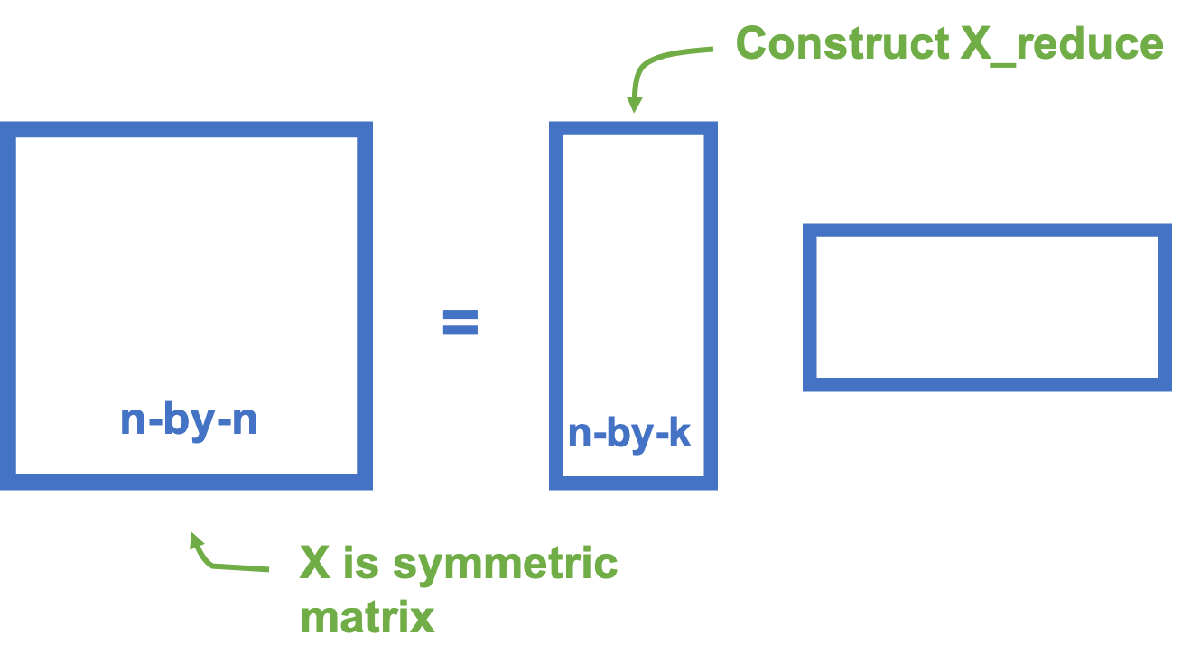

clc; clear; close all;
% addpath('../data')
% cd /Users/chloewang/Documents/VDMcourse/Summer-Camp-2022-in-Diffusion-Map/demo
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/demo'])

matrix_size = 210;
sparse_ratio = 0.7; % (n * sparse_ratio) entries are zeros
k = floor(sqrt(matrix_size));

reduce_X = normrnd(0, 1, matrix_size, k);
tmp = quantile(abs(reduce_X(:)), sparse_ratio);
reduce_X(abs(reduce_X)<tmp) = 0.0;
X = reduce_X*reduce_X'; % symmetrization
n_sparse = sum(sum(X == 0));
disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(['The sparse ratio is: ', num2str(round(n_sparse/matrix_size^2, 3))])

The sparse ratio is: 0.272


disp(X(1:5, 1:5))

   18.7948         0    3.5485   -5.1312   -0.5800
         0    5.1353         0   -1.7001         0
    3.5485         0   11.1327         0    4.3731
   -5.1312   -1.7001         0    7.9676    3.6658
   -0.5800         0    4.3731    3.6658   12.6096



## Eigen-decomposition

$X=USU^{-1} = USU^T$ where $U$ is o.n. matrix. Note that Frobenius norm is 2 norm of a matrix.

[U, S] = eig(X);
X_approx = full(U*S*U');

disp(['The Frobenius norm of two matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm of two matrix is 6.1374e-13.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

    3.1262   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000    6.2269   -0.0000    2.7101    3.6168
    0.0000   -0.0000    1.1708   -0.0000   -0.0000
   -0.0000    2.7101   -0.0000    8.4076   -0.0000
   -0.0000    3.6168   -0.0000   -0.0000    3.9439



## Sparse matrix

Usually, the transition matrix is sparse. Hence, using `eigs` might be faster. The Arnoldi iteration is applied.

num_largest_ev = 13; % how many eigenvector you hope to approximate original matrix
X_sparse = sparse(X);
[U, S] = eigs(X_sparse, num_largest_ev);
X_approx = full(U*S*U');

disp(['The Frobenius norm from approximation matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from approximation matrix is 99.4653.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

    2.7386    0.1446    0.2450    0.5522    0.1070
    0.1446    6.1729   -0.0914    2.5042    3.5769
    0.2450   -0.0914    1.0160   -0.3490   -0.0676
    0.5522    2.5042   -0.3490    7.6210   -0.1525
    0.1070    3.5769   -0.0676   -0.1525    3.9143



## Singular value decomposition (SVD)

This is low rank approximation method. Roseland reduced method is based on SVD.

$X=X_rX_r^T=(USV^T)(USV^T)^T = USSU^T$ where reduced matrix $X_r = USV^T$

num_largest_ev = 14;
[U, S, V] = svds(reduce_X, num_largest_ev);

X_approx = full(U*S*S*U');

disp(['The Frobenius norm from SVD matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from SVD matrix is 1.042e-12.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

    3.1262   -0.0000   -0.0000    0.0000   -0.0000
   -0.0000    6.2269   -0.0000    2.7101    3.6168
   -0.0000   -0.0000    1.1708   -0.0000   -0.0000
    0.0000    2.7101   -0.0000    8.4076   -0.0000
   -0.0000    3.6168   -0.0000   -0.0000    3.9439



## Application of SVD

I use 5, 10, 15, ..., 50 eigenvector to approximate original image.

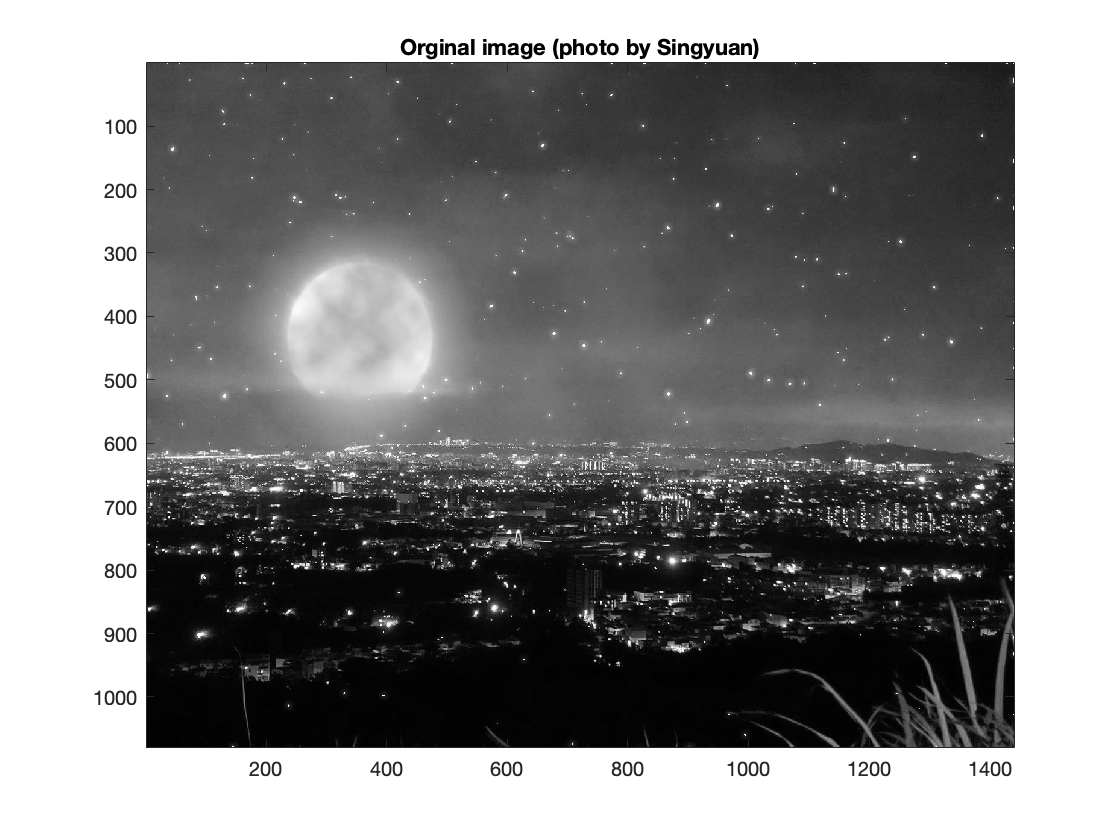

% X = imread('mountain.jpg');
% imshow(X)
% X = double(rgb2gray(X));
% X = X/255.0;
load('mountain_gray.mat')
mountain_gray;
figure
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')

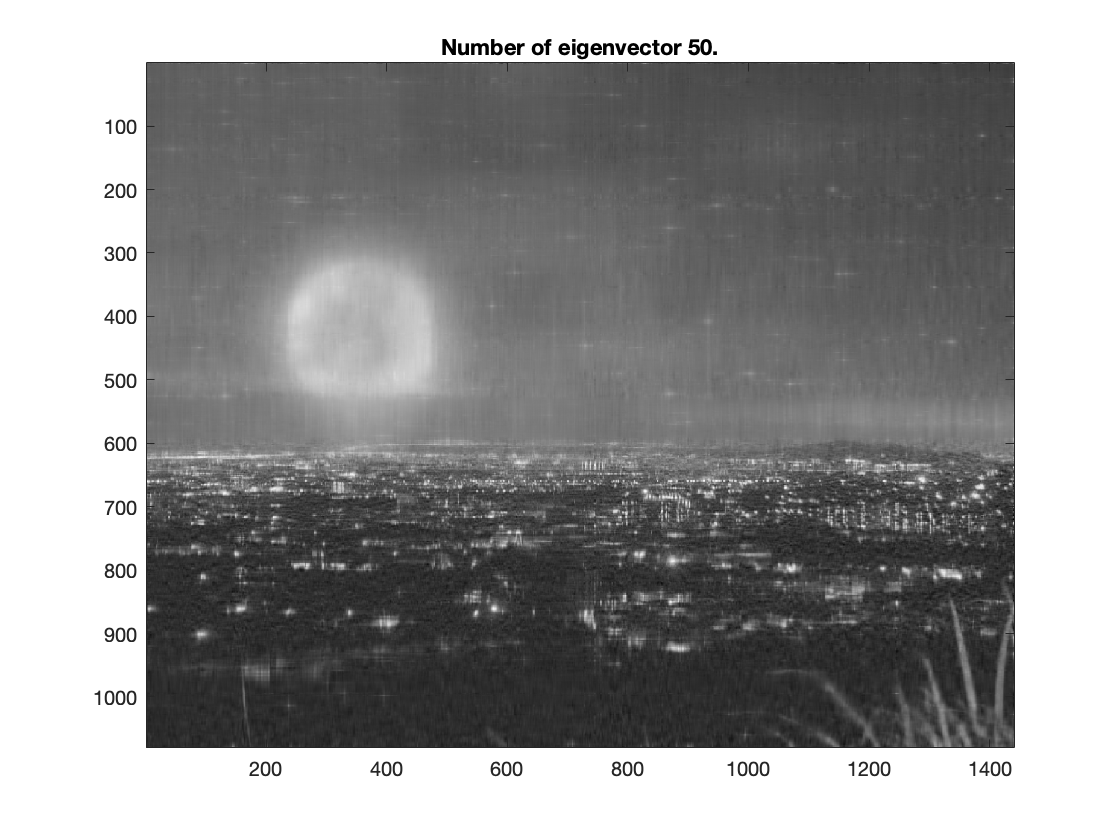

[U, S, V] = svd(mountain_gray);
figure
for i = 5:5:50
    imagesc(U(:, 1:i)*S(1:i, 1:i)*V(:, 1:i)');
    colormap(gray);
    title(['Number of eigenvector ', num2str(i), '.'])
    pause(0.5)
    drawnow
end

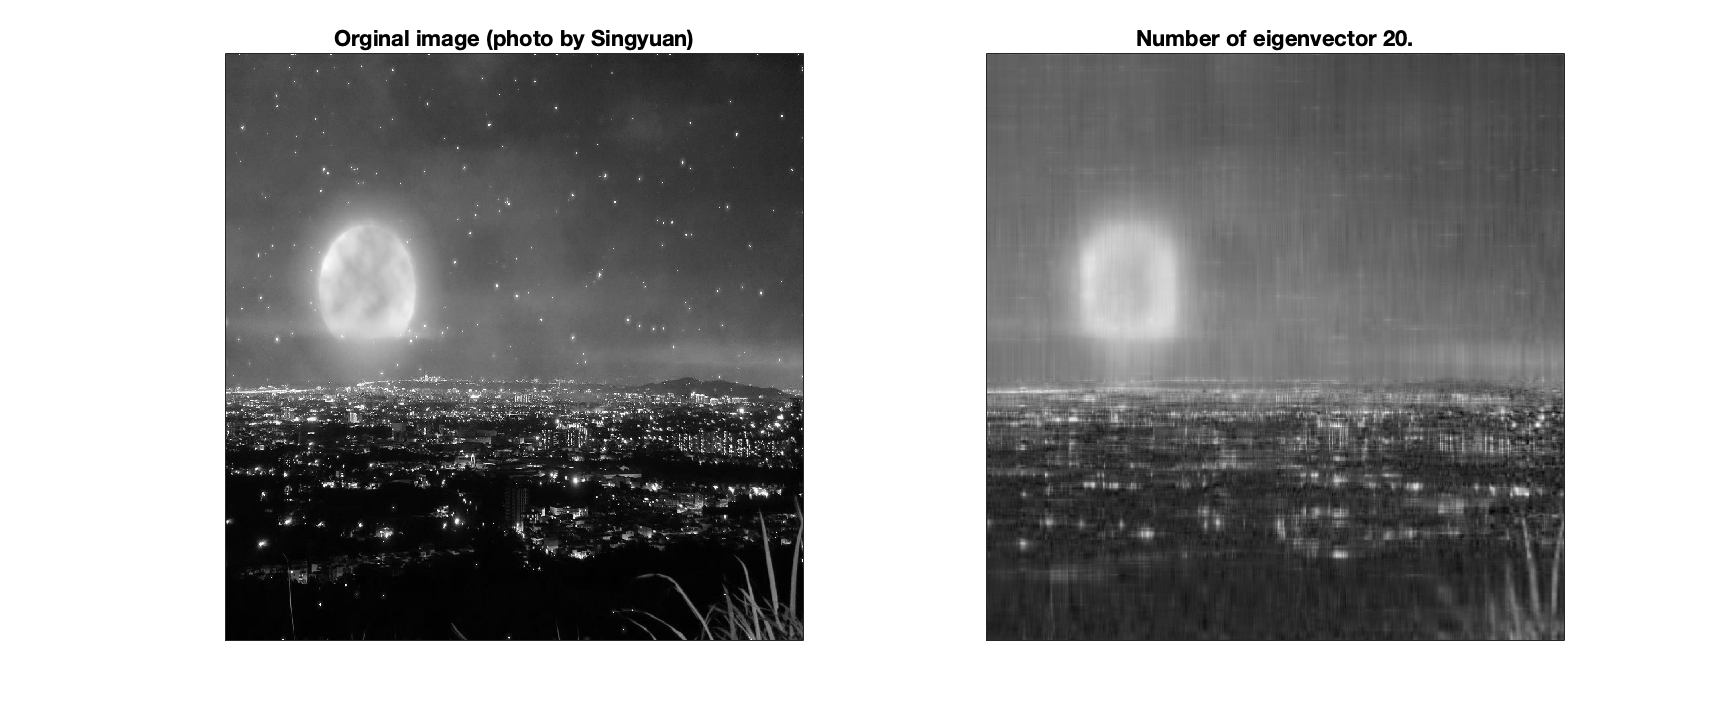

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1, 2, 1)
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')
set(gca,'xtick',[], 'ytick',[])
subplot(1, 2, 2)
imagesc(U(:, 1:20)*S(1:20, 1:20)*V(:, 1:20)');
colormap(gray);
title(['Number of eigenvector ', num2str(20), '.'])
set(gca,'xtick',[], 'ytick',[])